% Construct full file path
file_path = "C:\Users\Stefan.rudolph\Documents\output_signals.xlsx";

% Read data from Excel file
list_outputs = readcell(file_path);

% If you want to convert it to a MATLAB cell array of strings, you can do:
signal_out = list_outputs(:);

% Display the MATLAB cell array of strings
disp(signal_out);

    {'Anode_In_Pressure_bara'        }
    {'Anode_Out_Flow_gr_per_sec'     }
    {'Anode_Out_H2_mass_frac'        }
    {'Anode_Out_N2_mass_frac'        }
    {'Anode_Out_h2o_vap_mass_frac'   }
    {'Anode_Out_h2o_mass_frac'       }
    {'Anode_Out_Temperature_C'       }
    {'Cathode_In_Pressure_bara'      }
    {'Cathode_Out_Flow'              }
    {'Cathode_Out_O2_mass_frac'      }
    {'Cathode_Out_N2_mass_frac'      }
    {'Cathode_Out_h2o_vap_mass_frac' }
    {'Cathode_Out_h2o_mass_frac'     }
    {'Cathode_Out_Temperature_C'     }
    {'Cool_In_Pressure_bara'         }
    {'Cool_Out_Flow_gr_per_sec'      }
    {'Cool_Out_Temperature_C'        }
    {'Voltage_V'                     }
    {'Voltage_Loss_Activation_V'     }
    {'Voltage_Loss_Transport_V'      }
    {'Voltage_Loss_Ohmnic_V'         }
    {'Anode_Stoichiometric_Ratio'    }
    {'Cathode_Stoichiometric_Ratio'  }
    {'Membrane_Water_Content_Average'}
    {'Membrane_Water_Content_Vol_1'  }
    {'Membrane_Water_Cont

load("pc_fmu.mat");


disp(pc_fmu(:,51))

   1.0e+03 *

    0.0050
    0.0017
    0.0005
    0.0003
    0.0003
    0.0004
    0.0000
    0.0712
    0.0011
    0.0016
    0.1029
    0.0001
    0.0007
    0.0002
         0
    0.0803
    0.0020
    0.0021
    2.7912
    0.0763
    0.2992
    0.0565
    0.0032
    0.0494
    0.0057
    0.0039
    0.0060
    0.0076
    0.0067
    0.0044
    0.0006
    0.0008
    0.0008
    0.0008
    0.0006
    0.0004
    0.0006
    0.0007
    0.0007
    0.0006




out_end = zeros(39, 1);

for i = 2:40
    out_end(i-1,1) = pc_fmu(i, 51);
end

out_end;

t = pc_fmu(1, :);

anode_out_mf = pc_fmu(4:7, :);
cathode_out_mf = pc_fmu(12:15, :);
temperatures = pc_fmu([8,16,20], :);
pressures = pc_fmu([2,10,18], :);
voltages = pc_fmu(21:24, :);
RH_anode = pc_fmu(31:35, :);
RH_av_anode = sum(RH_anode(:,:))/5;
RH_cathode = pc_fmu(35:39, :);
RH_av_cathode = sum(RH_cathode(:,:))/5;
membrane = pc_fmu(25:30, :);

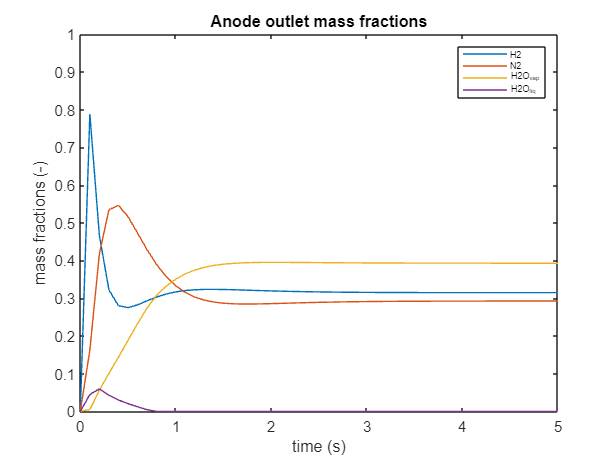



plot(t, anode_out_mf)
hold on
ylim([0, 1])
legend("H2" , "N2" , "H2O_vap" , "H2O_liq", 'Fontsize', 6)
xlabel("time (s)")
ylabel("mass fractions (-)")
title("Anode outlet mass fractions")
hold off

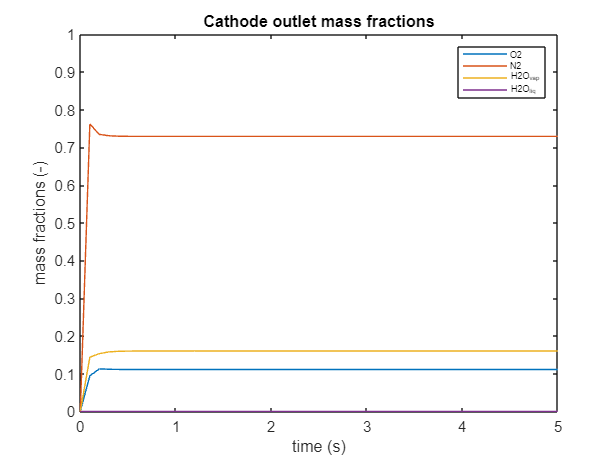



plot(t, cathode_out_mf)
hold on
ylim([0, 1])
legend("O2" , "N2" , "H2O_vap" , "H2O_liq", 'Fontsize', 6)
xlabel("time (s)")
ylabel("mass fractions (-)")
title("Cathode outlet mass fractions")
hold off

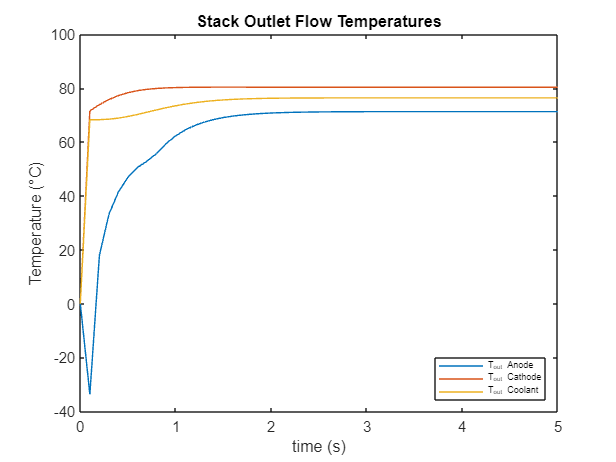


plot(t, temperatures)
hold on
ylim([-40, 100])
legend("T_out Anode" , "T_out Cathode" , "T_out Coolant" , "Location" , "southeast",'Fontsize', 6)
xlabel("time (s)")
ylabel("Temperature (°C)")
title("Stack Outlet Flow Temperatures")
hold off

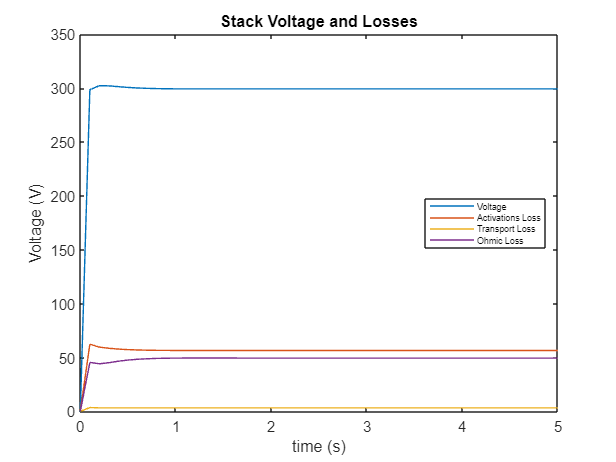


plot(t, voltages)
hold on
ylim([0, 350])
legend("Voltage" , "Activations Loss" , "Transport Loss" , "Ohmic Loss", "Location" , "east",'Fontsize', 6)
xlabel("time (s)")
ylabel("Voltage (V)")
title("Stack Voltage and Losses")
hold off

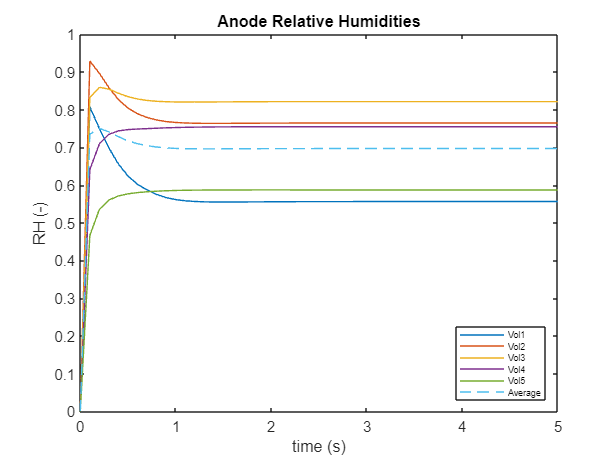


plot(t, RH_anode)
hold on
plot(t, RH_av_anode, "--")
ylim([0, 1])
legend("Vol1" , "Vol2" , "Vol3" , "Vol4","Vol5" , "Average" , "Location" , "southeast",  'Fontsize', 6)
xlabel("time (s)")
ylabel("RH (-)")
title("Anode Relative Humidities")
hold off

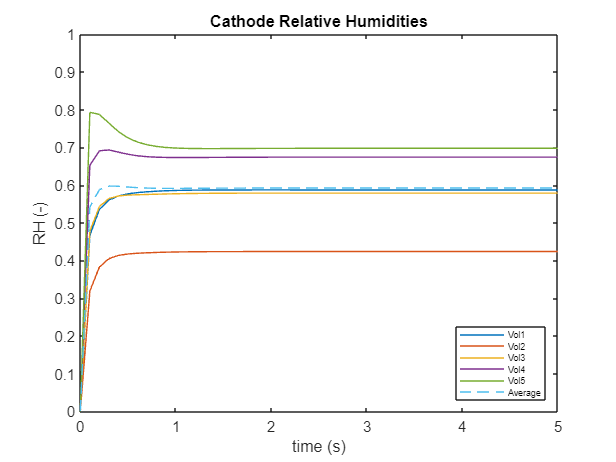


plot(t, RH_cathode)
hold on
plot(t, RH_av_cathode, "--")
ylim([0, 1])
legend("Vol1" , "Vol2" , "Vol3" , "Vol4","Vol5" , "Average" , "Location" , "southeast",  'Fontsize', 6)
xlabel("time (s)")
ylabel("RH (-)")
title("Cathode Relative Humidities")
hold off

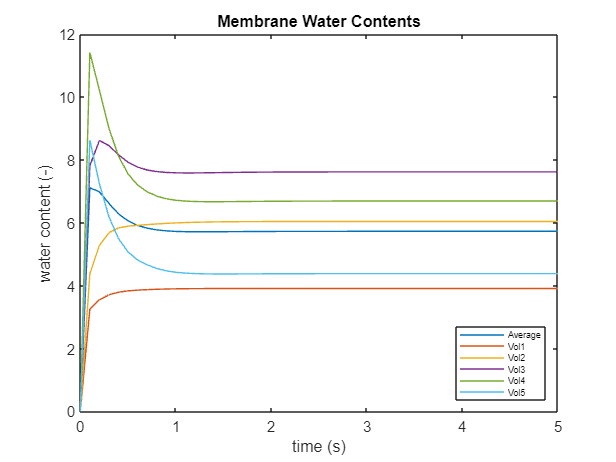


plot(t, membrane)
hold on
ylim([0, 12])
legend("Average", "Vol1" , "Vol2" , "Vol3" , "Vol4","Vol5" , "Location" , "southeast",  'Fontsize', 6)
xlabel("time (s)")
ylabel("water content (-)")
title("Membrane Water Contents")
hold off

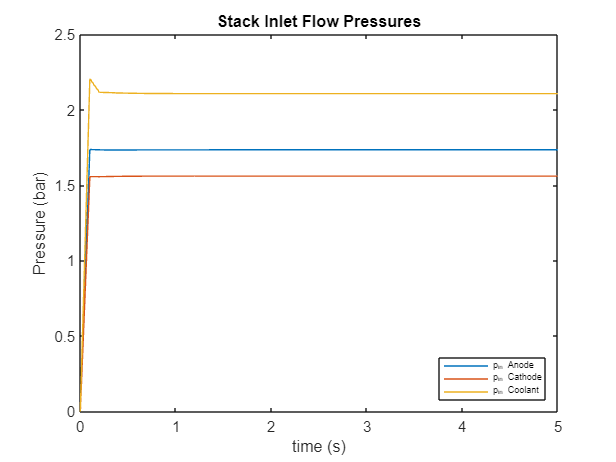


plot(t, pressures)
hold on
ylim([0, 2.5])
legend("p_in Anode" , "p_in Cathode" , "p_in Coolant" , "Location" , "southeast",'Fontsize', 6)
xlabel("time (s)")
ylabel("Pressure (bar)")
title("Stack Inlet Flow Pressures")
hold off